close all
clear
opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Ark1";
opts.DataRange = "A2:D600002";

% Specify column names and types
opts.VariableNames = ["Domain", "V2_1", "Domain_1", "I2_1", "Domain_2", "V3"];
opts.VariableTypes = ["double", "double", "double", "double", "double","double"];

% Import the data
data = readtable("C:\Users\frede\OneDrive\Skrivebord\46715-assignment\46715_data", opts, "UseExcel", false); %Change filepath
data = table2array(data)

data = 1.0e+03 *

         0         0         0         0         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


clear opts

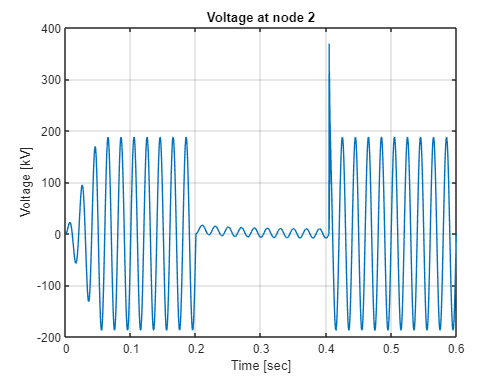

t = data(:,1);
v = data(:,2);
plot(t,v)
xlabel('Time [sec]');ylabel('Voltage [kV]');title('Voltage at node 2');grid on;

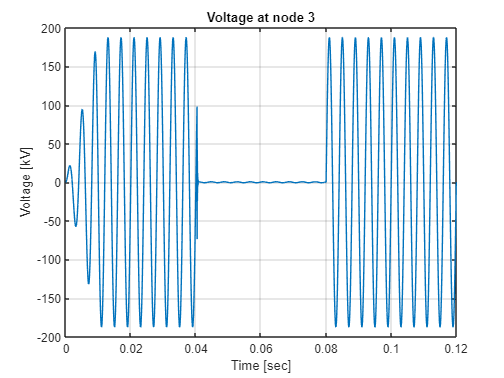

t = data(:,1);
v = data(:,6);
plot(t,v)
xlabel('Time [sec]');ylabel('Voltage [kV]');title('Voltage at node 3');grid on;

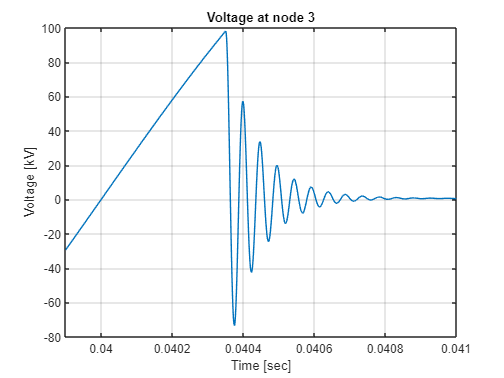


t = data(:,1);
v = data(:,6);
plot(t,v)
xlabel('Time [sec]');ylabel('Voltage [kV]');title('Voltage at node 3');grid on;
xlim([0.0399,0.041])